Cl_max=2.5

Cl_max = 2.5000

vmax=140

vmax = 140

Cl_neg=-5

Cl_neg = -5

w_s=1200

w_s = 1200

ceiling=6000

ceiling = 6000

sigma=(1-6.873*10^(-6)*ceiling)^4.26

sigma = 0.8358

V=0:1:150

V =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


n=0.5*row*sigma*Cl_max*V.^2/w_s

n =          0    0.0011    0.0043    0.0096    0.0171    0.0267    0.0384    0.0523    0.0683    0.0864    0.1066    0.1290    0.1536    0.1802    0.2090    0.2400    0.2730    0.3082    0.3455    0.3850    0.4266    0.4703    0.5162    0.5642    0.6143    0.6666    0.7209    0.7775    0.8361    0.8969    0.9598    1.0249    1.0921    1.1614    1.2329    1.3064    1.3822    1.4600    1.5400    1.6221    1.7064    1.7928    1.8813    1.9719    2.0647    2.1596    2.2567    2.3559    2.4572    2.5606


n_neg=0.5*row*sigma*Cl_neg*V.^2/w_s

n_neg =          0   -0.0021   -0.0085   -0.0192   -0.0341   -0.0533   -0.0768   -0.1045   -0.1365   -0.1728   -0.2133   -0.2581   -0.3071   -0.3605   -0.4181   -0.4799   -0.5460   -0.6164   -0.6911   -0.7700   -0.8532   -0.9406   -1.0324   -1.1283   -1.2286   -1.3331   -1.4419   -1.5549   -1.6722   -1.7938   -1.9197   -2.0498   -2.1842   -2.3228   -2.4657   -2.6129   -2.7643   -2.9200   -3.0800   -3.2442   -3.4127   -3.5855   -3.7625   -3.9438   -4.1294   -4.3192   -4.5133   -4.7117   -4.9143   -5.1212


n_limit=3*ones(1,length(V))

n_limit =      3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3     3


n_ultimate=9*ones(1,length(V))

n_ultimate =      9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9     9


n_neg_limit=-1.8*ones(1,length(V))

n_neg_limit =    -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000   -1.8000


n_neg_ultimate=-5*ones(1,length(V))

n_neg_ultimate =     -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5    -5


n_vmax=-30:1:40

n_vmax =    -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19


V_max=vmax*ones(1,length(n_vmax))

V_max =    140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140   140


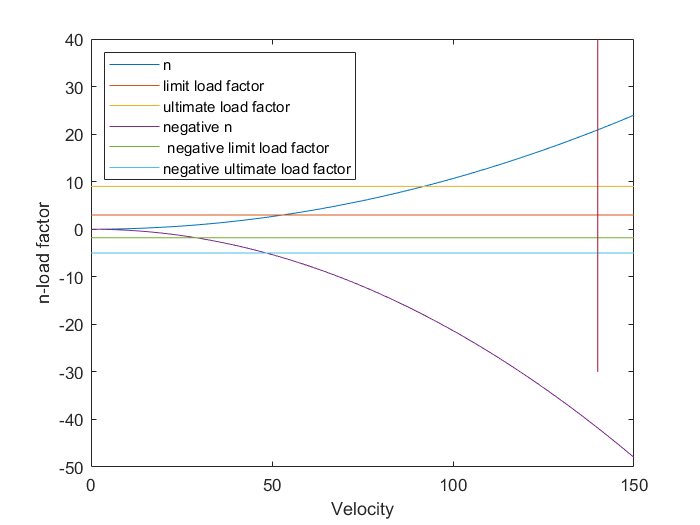

plot(V,n)
hold on
plot(V,n_limit)
plot(V,n_ultimate)
plot(V,n_neg)
plot(V,n_neg_limit)
plot(V,n_neg_ultimate)
plot(V_max,n_vmax)
hold off
xlabel("Velocity")
ylabel("n-load factor")
legend("n","limit load factor","ultimate load factor","negative n"," negative limit load factor","negative ultimate load factor","Location","northwest")